# Magetic in TB

## Stoner model

### Stoner model of ferromagnetism

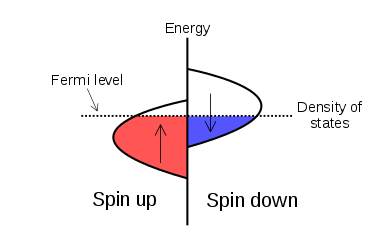

Some **metals** have narrow bands and a large density of states at the Fermi level; This leads to a large Pauli susceptibility 


$$\chi_{\;\textrm{pauli}} \approx 2\mu_0 N\left(E_F \right)\mu_B^2$$


When $\chi_{\;\textrm{pauli}}$ is large enough, it is possible for the band to split spontaneously, and ferromagnetism appears.

A schematic band structure for the Stoner model of ferromagnetism. An exchange interaction has split the energy of states with different spins, and states near the [Fermi energy](https://en.wikipedia.org/wiki/Fermi_energy) $E_F$ are spin-polarized.


$$H_{s}=\sum_{k \sigma}\left(\varepsilon_{k}+I\left\langle n_{-\sigma}\right\rangle\right) c_{k \sigma}^{\dagger} c_{k \sigma}$$


I is a Stoner interatomic exchange parameter.(temperature-dependent)

Stoner model to other model

The Stoner model can be obtained from the [Hubbard model](https://en.wikipedia.org/wiki/Hubbard_model) by applying the [mean-field approximation](https://en.wikipedia.org/wiki/Mean_field_theory). 


$$H_{h}=\sum_{i j \sigma} t_{i j} c_{i \sigma}^{\dagger} c_{j \sigma}+\sum_{i} U n_{i \uparrow} n_{i \downarrow}$$


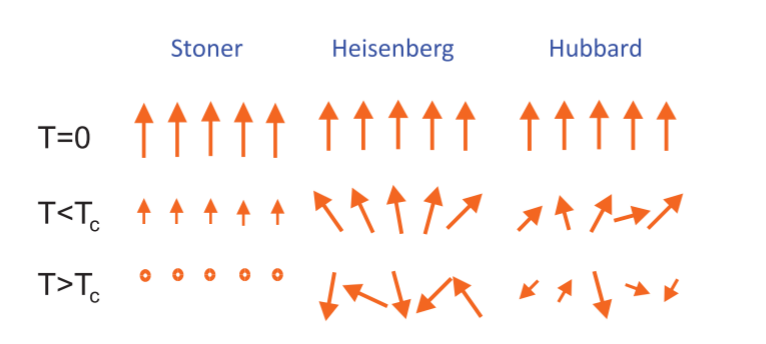

Schematic view of different models of magnetism: Stoner model for itinerant weakly correlated electrons, Heisenberg model for localized magnetic moments and Hubbard model for the spin-fluctuations model of correlated electrons.

## Peierls substitution

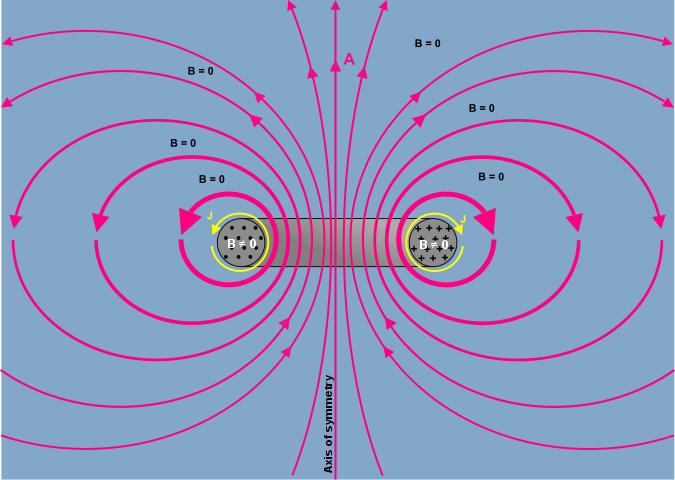

### Properties

### Harper Model - [Hofstadter Hamiltonian](https://en.wikipedia.org/wiki/Hofstadter%27s_butterfly)

The model, which was first analyzed in the 1950s by Rudolph Peierls and his student P. G. Harper, describes independent electrons on a **2D lattice**, acted on by a homogeneous magnetic field. $\phi =\frac{{\textrm{Ba}}^2 }{\phi_0 }$

$E_0$($\psi_{m+1}$ +$\psi_{m-1}$  + 2cos($2\pi \phi m$ + $\delta$)$\psi_m$) = $E\psi_m$

It is a realistic single-band model for an electron moving in a plane, with a spatially periodic potential, and a uniform magnetic field perpendicular to the plane.

**Note, again, the two-dimensional problem is reduced to one-dimensional problem.**

The parameter $\phi$ that appears in Harper equation is the pure number 

#### **Bloch Theorem**

- **For rational flux, let **$\phi =\frac{p}{q}$

Harper equation describes a system that is periodic with period q. Such systems can be studied using “ **Bloch Theorem**”

put this system in square lattice;

$\delta ={\textrm{ak}}_y$,$\psi_{m+1} ={e^{{\textrm{iak}}_x \;} \psi }_m$,$\psi_{m-1} ={e^{-{\textrm{iak}}_x \;} \psi }_m$

$E_0$(2cos(${\textrm{ak}}_x$)  + 2cos($2\pi \phi m$ - ${\textrm{ak}}_y$))$\psi_m$ = $E\psi_m$


$$E_0 \left\lbrack \begin{array}{ccccccc}
2C_1  & e^{{\textrm{ik}}_x }  & 0 & 0 & \ldotp  & 0 & e^{-{\textrm{iak}}_x } \\
e^{-{\textrm{iak}}_x }  & 2C_2  & e^{{\textrm{ik}}_x }  & 0 & 0 & \ldotp  & 0\\
0 & e^{-{\textrm{iak}}_x }  & 2C_3  & e^{{\textrm{ik}}_x }  & 0 & \ldotp  & 0\\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & 0\\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
e^{{\textrm{ik}}_x }  & 0 & \ldotp  & \ldotp  & 0 & e^{-{\textrm{iak}}_x }  & 2C_q 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\psi_1 \\
\psi_2 \\
\psi_3 \\
\ldotp \\
\ldotp \\
\ldotp \\
\psi_q 
\end{array}\right\rbrack =E\left\lbrack \begin{array}{c}
\psi_1 \\
\psi_2 \\
\psi_3 \\
\ldotp \\
\ldotp \\
\ldotp \\
\psi_q 
\end{array}\right\rbrack ,\textrm{where}\;C_n =\cos \left(2\pi n\phi -{\textrm{ak}}_y \right)$$


H_butterfly =@(q,p,E_0,a,k_x,k_y,OpenBoudary) ...
E_0.*(diag(2*cos(2*pi*(p/q)*(1:q)-a*k_y))+ ...
diag(exp(1i*a*k_x)*ones([1 q-1]),1)+exp(-1i*a*k_x)*diag(ones([1 q-1]),-1) + ...
(OpenBoudary~=1).*(diag(exp(-1i*a*k_x),q-1)+diag(exp(1i*a*k_x),-(q-1))));
%
H_butterfly(5,sym('p'),sym('E_0'),sym('a'),sym('k_x'),sym('k_y'),0)

$$ans = \begin{array}{l} \left(\begin{array}{ccccc} 2\,E_{0}\,\cos\left(\frac{2\,\pi \,p}{5}-a\,k_{y}\right) & \sigma_{2} & 0 & 0 & \sigma_{1}\\ \sigma_{1} & 2\,E_{0}\,\cos\left(\frac{4\,\pi \,p}{5}-a\,k_{y}\right) & \sigma_{2} & 0 & 0\\ 0 & \sigma_{1} & 2\,E_{0}\,\cos\left(\frac{6\,\pi \,p}{5}-a\,k_{y}\right) & \sigma_{2} & 0\\ 0 & 0 & \sigma_{1} & 2\,E_{0}\,\cos\left(\frac{8\,\pi \,p}{5}-a\,k_{y}\right) & \sigma_{2}\\ \sigma_{2} & 0 & 0 & \sigma_{1} & 2\,E_{0}\,\cos\left(2\,\pi \,p-a\,k_{y}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=E_{0}\,{\mathrm{e}}^{-a\,k_{x}\,\mathrm{i}}\\ \sigma_{2}=E_{0}\,{\mathrm{e}}^{a\,k_{x}\,\mathrm{i}} \end{array}$$

- For $\phi =1$


$$E(\overrightarrow{\mathrm{k}})=2 E_{0}\left(\cos k_{\mathrm{x}} a+\cos k_{\mathrm{y}} a\right)=E_{0}\left(e^{i k_{x} a}+e^{-i k_{x} a}+e^{i k_{y} a}+e^{-i k_{y} a}\right)$$


H_butterfly(1,sym('1'),sym('E_0'),sym('a'),sym('k_x'),sym('k_y'),0)

$$ans = E_{0}\,\left(2\,\cos\left(a\,k_{y}\right)+{\mathrm{e}}^{-a\,k_{x}\,\mathrm{i}}+{\mathrm{e}}^{a\,k_{x}\,\mathrm{i}}\right)$$

- For $\phi =\frac{1}{2}$


$$E_{\pm } =\pm 2\sqrt{\cos^2 k_x +\cos^2 k_y }$$


(H_butterfly(2,sym('1'),sym('E_0'),sym('a'),sym('k_x'),sym('k_y'),0))

$$ans = \left(\begin{array}{cc} -2\,E_{0}\,\cos\left(a\,k_{y}\right) & E_{0}\,\left({\mathrm{e}}^{-a\,k_{x}\,\mathrm{i}}+{\mathrm{e}}^{a\,k_{x}\,\mathrm{i}}\right)\\ E_{0}\,\left({\mathrm{e}}^{-a\,k_{x}\,\mathrm{i}}+{\mathrm{e}}^{a\,k_{x}\,\mathrm{i}}\right) & 2\,E_{0}\,\cos\left(a\,k_{y}\right) \end{array}\right)$$

eig(simplify(ans))

$$ans = \left(\begin{array}{c} -2\,E_{0}\,\sqrt{{\cos\left(a\,k_{x}\right)}^{2}+{\cos\left(a\,k_{y}\right)}^{2}}\\ 2\,E_{0}\,\sqrt{{\cos\left(a\,k_{x}\right)}^{2}+{\cos\left(a\,k_{y}\right)}^{2}} \end{array}\right)$$

- For $\phi =\frac{1}{3}$, the three bands having energies $E_0 \;$, $E_1 \;$, and$E_2 \;$are given by


$$E_i =2\sqrt{2}\cos \left(\theta \pm \frac{\textrm{i2}}{3}\pi \right),\textrm{Here}\;\theta =\frac{1}{3}\arccos \left\lbrack \frac{\cos \left(3{\textrm{ak}}_x \right)+\cos \left(3{\textrm{ak}}_y \right)}{2\sqrt{2}}\right\rbrack$$


H_butterfly(3,sym('1'),sym('E_0'),sym('a'),sym('k_x'),sym('k_y'),0)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} 2\,E_{0}\,\cos\left(\frac{2\,\pi }{3}-a\,k_{y}\right) & \sigma_{2} & \sigma_{1}\\ \sigma_{1} & 2\,E_{0}\,\cos\left(\frac{4\,\pi }{3}-a\,k_{y}\right) & \sigma_{2}\\ \sigma_{2} & \sigma_{1} & 2\,E_{0}\,\cos\left(a\,k_{y}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=E_{0}\,{\mathrm{e}}^{-a\,k_{x}\,\mathrm{i}}\\ \sigma_{2}=E_{0}\,{\mathrm{e}}^{a\,k_{x}\,\mathrm{i}} \end{array}$$

simplify(eig(ans))

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{2^{1/3}\,\left(2\,{E_{0}}^{2}+\sigma_{1}\right)}{\sigma_{3}}\\ -\frac{2^{1/3}\,\left(2\,\sqrt{3}\,{E_{0}}^{2}\,\mathrm{i}+2\,{E_{0}}^{2}+\sigma_{1}-\sigma_{2}\right)}{2\,\sigma_{3}}\\ -\frac{2^{1/3}\,\left(2\,{E_{0}}^{2}-2\,\sqrt{3}\,{E_{0}}^{2}\,\mathrm{i}+\sigma_{1}+\sigma_{2}\right)}{2\,\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2^{1/3}\,\sigma_{4}}{2}\\ \sigma_{2}=\frac{2^{1/3}\,\sqrt{3}\,\sigma_{4}\,\mathrm{i}}{2}\\ \sigma_{3}={\left(2\,{\left|E_{0}\right|}^{3}\,\sqrt{{\cos\left(3\,a\,k_{x}\right)}^{2}+2\,\cos\left(3\,a\,k_{x}\right)\,\sigma_{5}+{\sigma_{5}}^{2}-8}+2\,{E_{0}}^{3}\,\sigma_{5}+{E_{0}}^{3}\,{\mathrm{e}}^{-3\,a\,k_{x}\,\mathrm{i}}+{E_{0}}^{3}\,{\mathrm{e}}^{3\,a\,k_{x}\,\mathrm{i}}\right)}^{1/3}\\ \sigma_{4}={\left(2\,{\left|E_{0}\right|}^{3}\,\sqrt{{\cos\left(3\,a\,k_{x}\right)}^{2}+2\,\cos\left(3\,a\,k_{x}\right)\,\sigma_{5}+{\sigma_{5}}^{2}-8}+2\,{E_{0}}^{3}\,\sigma_{5}+{E_{0}}^{3}\,{\mathrm{e}}^{-3\,a\,k_{x}\,\mathrm{i}}+{E_{0}}^{3}\,{\mathrm{e}}^{3\,a\,k_{x}\,\mathrm{i}}\right)}^{2/3}\\ \sigma_{5}=\cos\left(3\,a\,k_{y}\right) \end{array}$$

- For $\phi =\frac{1}{4}$, the three bands having energies $E_{++} \;$, $E_{+-} \;$, $E_{-+} \;$and$E_{--} \;$are given by


$$E_{\pm \pm \;} =\pm \sqrt{4\pm 2\left\lbrack 3+\frac{1}{2}\left(\cos \left(4{\textrm{ak}}_x \right)+\cos \left(4{\textrm{ak}}_y \right)\right)\right\rbrack \;}$$


H_butterfly(4,sym('1'),sym('E_0'),sym('a'),sym('k_x'),sym('k_y'),0)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} 2\,E_{0}\,\cos\left(\frac{\pi }{2}-a\,k_{y}\right) & \sigma_{2} & 0 & \sigma_{1}\\ \sigma_{1} & -2\,E_{0}\,\cos\left(a\,k_{y}\right) & \sigma_{2} & 0\\ 0 & \sigma_{1} & 2\,E_{0}\,\cos\left(\frac{3\,\pi }{2}-a\,k_{y}\right) & \sigma_{2}\\ \sigma_{2} & 0 & \sigma_{1} & 2\,E_{0}\,\cos\left(a\,k_{y}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=E_{0}\,{\mathrm{e}}^{-a\,k_{x}\,\mathrm{i}}\\ \sigma_{2}=E_{0}\,{\mathrm{e}}^{a\,k_{x}\,\mathrm{i}} \end{array}$$

- For every rational flux  $\phi =\frac{p}{q}$, there are q bands. In other words, a single band fo**r zero magnetic field** splits i**nto q bands** when magnetic flux is a r**ational number with denominator q**

- For **q-even**, two bands touch at **E=0**. there exists Dirac Fermion at E = 0

#### q = 2

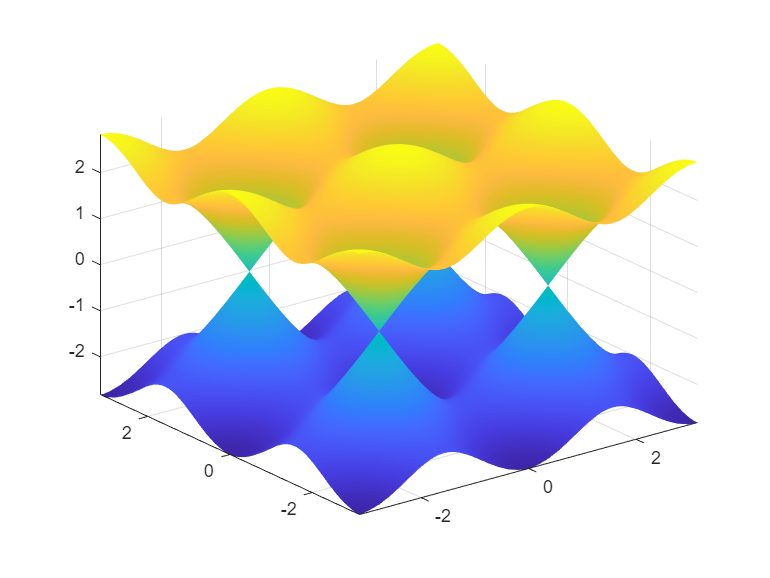

H_butterfly_sym = simplify(H_butterfly(2,1,1,1,sym('k_x'),sym('k_y'),0));
fsurf(eig(H_butterfly_sym),[-pi pi -pi pi],'LineStyle','none')

Flux-1/2 is the simplest case as the Hamiltonian is a 2 × 2 matrix and hence describes a spin-1/2 model in a magnetic field.

#### q = 4

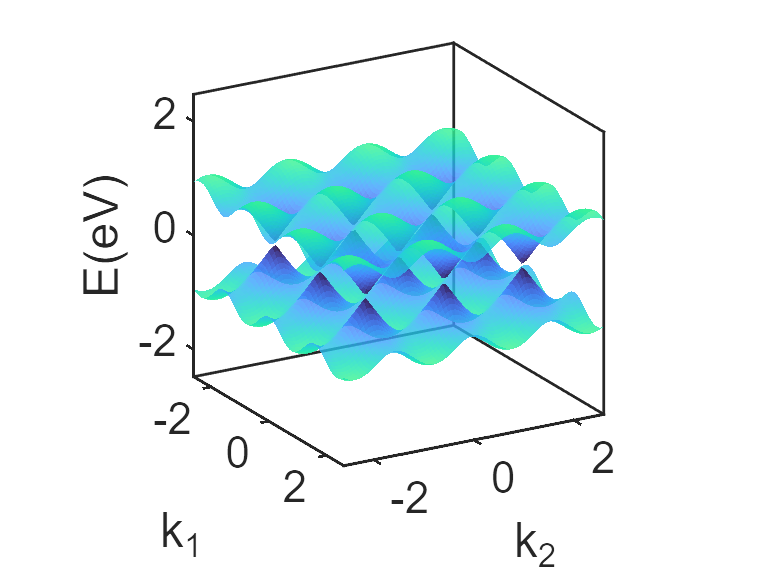

q = 4;Nodes = 100;
EIGENCAR_3D = zeros(Nodes,Nodes,q);i = 0;j=0;
k_x_L = linspace(-pi,pi,Nodes);
k_y_L = linspace(-pi,pi,Nodes);
for k_x = k_x_L
    i = i+1;j=0;
    for k_y = k_y_L
        j = j+1;
        EIGENCAR_3D(i,j,:) = eig(H_butterfly(q,1,1,1,k_x,k_y,0));
    end
end
vasplib.bandplot_3d(EIGENCAR_3D,k_x_L,k_y_L);view(60,20);

#### q = 6 

H_butterfly_1D in a ctkubdric geometry

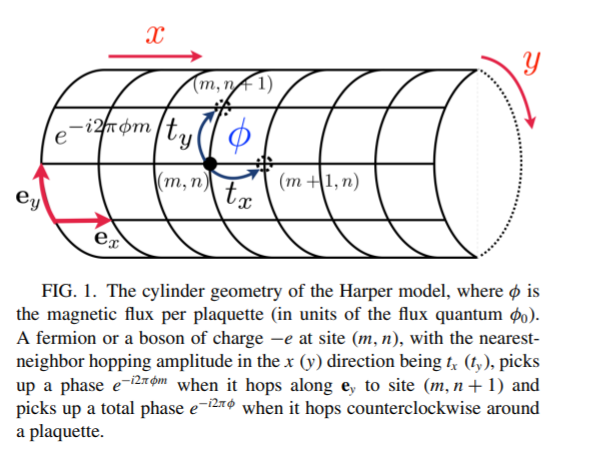

10.1103/PhysRevB.104.165140

H_butterfly_1D =@(phi,E_0,a,m,k_y) ...
E_0*(diag(2*cos(2*pi*(phi).*(1:m)-a*k_y))+...
diag(ones([1 m-1]),1)+diag(ones([1 m-1]),-1));%+diag(1,m-1)+diag(1,1-m));
H_butterfly_1D(sym('phi'),1,1,5,sym('k_y'))

$$ans = \left(\begin{array}{ccccc} 2\,\cos\left(k_{y}-2\,\pi \,\varphi \right) & 1 & 0 & 0 & 0\\ 1 & 2\,\cos\left(k_{y}-4\,\pi \,\varphi \right) & 1 & 0 & 0\\ 0 & 1 & 2\,\cos\left(k_{y}-6\,\pi \,\varphi \right) & 1 & 0\\ 0 & 0 & 1 & 2\,\cos\left(k_{y}-8\,\pi \,\varphi \right) & 1\\ 0 & 0 & 0 & 1 & 2\,\cos\left(k_{y}-10\,\pi \,\varphi \right) \end{array}\right)$$

q = 6;v= 1;m=q*100-v;Nodes = 100;phi = 1/q;

m = q*N-v; 

v= 0;v=1;v=2;

This fact leads to a spectrum that shares the exact same functional form for the cylinder with ν = 1 and the torus with general twisted boundary conditions. Because of this functional form, bulk energies for a finite cylinder of length QN − 1 correspond to exact energies for a finite torus with periodic and antiperiodic boundary conditions of length QN.

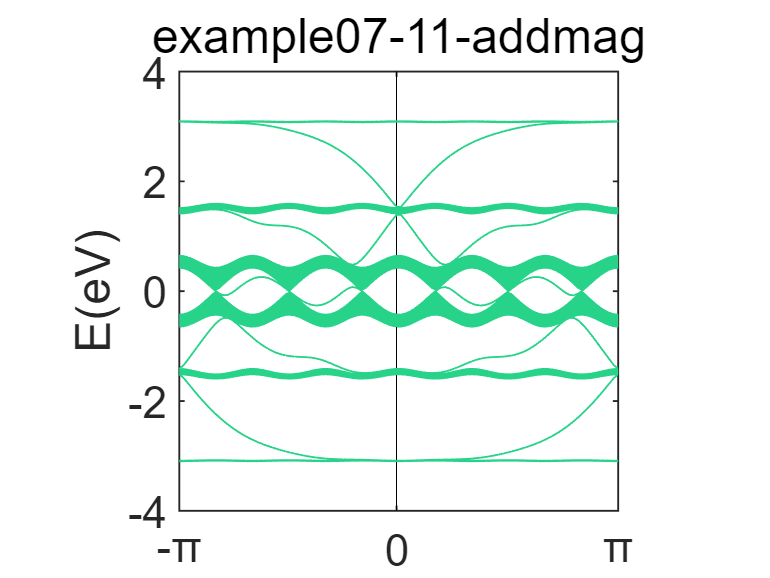

EIGENCAR_1D = zeros(m,Nodes);j=0;
k_y_L = linspace(-pi,pi,Nodes);
for k_y = k_y_L
    j = j+1;
    EIGENCAR_1D(:,j) = eig(H_butterfly_1D(phi,1,1,m,k_y));
end
bandplot(EIGENCAR_1D,[-4,4],k_y_L,k_y_L([1 Nodes/2 Nodes]),["-\pi" "0" "\pi"]);

#### Real space form: Hofstadter model

$H=E_0 \left(\sum_{m,n} {c^{\dagger \;} }_{m+1,n} c_{m,n} +e^{-\textrm{i2}\pi \phi m} \sum_{m,n} {c^{\dagger \;} }_{m,n+1} c_{m,n} \right)+$h.c.

H_butterfly_up =@(m,n,phi,E_0) ...
    kron(diag(E_0*ones(1,m-1),1),eye(n))+...
    kron(diag(exp(-1i*2*pi*phi.*(1:m))),diag(E_0*ones(1,n-1),1));
H_butterfly_r =@(m,n,phi,E_0) H_butterfly_up(m,n,phi,E_0) +H_butterfly_up(m,n,phi,E_0)';
H_butterfly_r(2,2,sym('phi','real'),sym('E_0','real'))

$$ans = \left(\begin{array}{cccc} 0 & E_{0}\,{\mathrm{e}}^{-2\,\pi \,\varphi \,\mathrm{i}} & E_{0} & 0\\ E_{0}\,{\mathrm{e}}^{2\,\pi \,\varphi \,\mathrm{i}} & 0 & 0 & E_{0}\\ E_{0} & 0 & 0 & E_{0}\,{\mathrm{e}}^{-4\,\pi \,\varphi \,\mathrm{i}}\\ 0 & E_{0} & E_{0}\,{\mathrm{e}}^{4\,\pi \,\varphi \,\mathrm{i}} & 0 \end{array}\right)$$

Here we take  $E_0 =1$, m = n

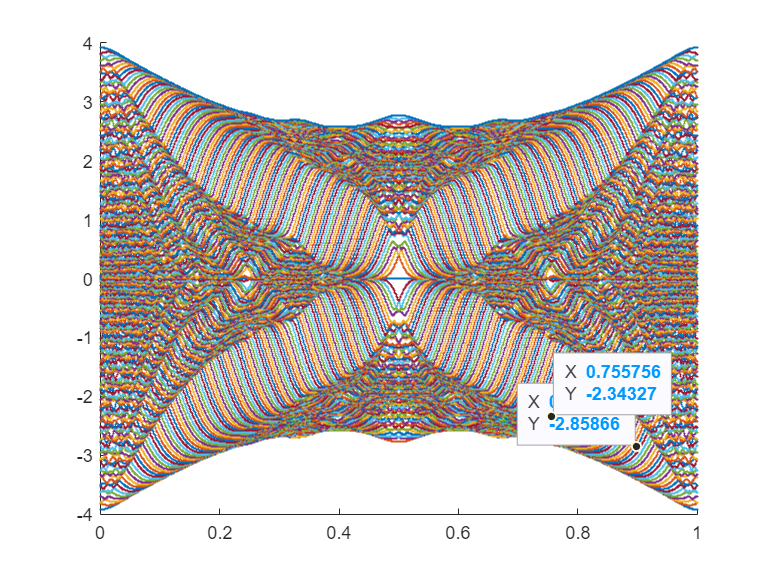

H_butterH_butterfly_square = @(n,phi) eig(H_butterfly_r(n,n,phi,1));
n = 15;
phi_interval = 1000;
H_butterH_butterfly_n = @(phi)H_butterH_butterfly_square(n,phi);
phiL= linspace(0,1,phi_interval);EIGENCAR = zeros(n^2,phi_interval);
for i =1:numel(phiL)
    EIGENCAR(:,i) = H_butterH_butterfly_n(phiL(i));
end
figure();scatter(phiL,EIGENCAR,20/n,'filled');

#### Butterfly diagram to Wannier diagram

Wannier Phys. Stat. Sol. (1978)

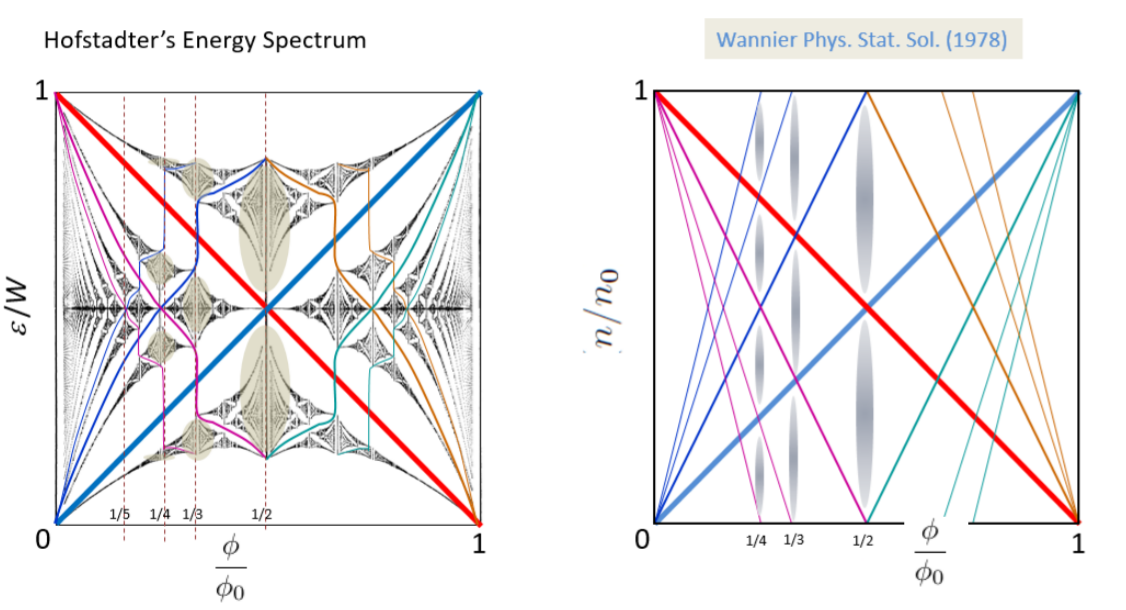

The bandgap in the butterfly can be described by a Dipphantine equation


$$\frac{n}{n_0 }=t\left(\frac{\phi }{\phi_0 }\right)+s$$


#### Relation to laudau level

replacing the crystal momentum with the canonical momentum 


$$\hbar k\to p-\textrm{qA},p=\;\left(p_x ,p_y \right),q\;\textrm{is}\;\textrm{the}\;\textrm{electron}\;\textrm{charge}\left(-e\right),A\;\textrm{is}\;\textrm{the}\;\textrm{magnetic}\;\textrm{vector}\;\textrm{potential}\left(A=\left(A_x ,A_y ,0\right)=\left(B_z y,B_z x,0\right)\right),$$



$$W\left(k\right)\to W\left(p-\textrm{qA}\right)$$



$$W\left(p-\textrm{qA}\right)=E_0 \left(e^{i\frac{\left(p_x -{\textrm{qA}}_x \right)}{\hbar }\;a} +e^{-i\frac{\left(p_x -{\textrm{qA}}_x \right)}{\hbar }\;a} +e^{i\frac{\left(p_y -{\textrm{qA}}_y \right)}{\hbar }\;a} +e^{-i\frac{\left(p_y -{\textrm{qA}}_y \right)}{\hbar }\;a} \right)$$
 

Taylor expantion arond p = 0;


$$H_0 =\frac{2a^2 }{\hbar^2 }{\left(p-\mathrm{qA}\right)}^2 +\varepsilon_0 =\frac{1}{2m}{\left(p-\mathrm{qA}\right)}^2 +\varepsilon_{0\;}$$


consist with a magnetic field when added 

Use Laudau Gauge (replace $k\to k+\frac{\mathrm{qA}}{\hbar c}$)(Gauss Unit)

A = (0, Bx,0) for Bz noraml 

The harper equation($E_0 =1$) can be written as 


$$2\cos \left({\mathrm{ak}}_X \right)+2c\mathrm{os}\left({\mathrm{ak}}_y -\frac{\mathrm{eBx}}{\hbar c}a\right)$$


discrete kx and ky

$\left(u_{n+1} +u_{n-1} \right)+2c\mathrm{os}\left(\alpha n\right)$ where$\alpha =\frac{\phi ={\mathrm{Ba}}^2 }{\phi_0 =\frac{\hbar c}{e}},$

### Derivation from wannier 

$H=\frac{p^2 }{2m}+U\left(r\right),U\left(r\right)$is the potential landscape due to the crystal lattuce.

By the condtion of perodic potiential assumption, the hamiltonian can be solved by Bloch theorem

$H\psi_k \left(r\right)=E\left(k\right)\psi_k \left(r\right)$,where $\psi_k \left(r\right)=\frac{1}{\sqrt{N}}\sum_R e^{\textrm{ik}\cdot R} \phi_R \left(r\right),$ $\phi_R \left(r\right)$ are known as [Wannier functions](https://en.wikipedia.org/wiki/Wannier_function).


$$E(\mathbf{k})=\int d \mathbf{r} \Psi_{\mathbf{k}}^{*}(\mathbf{r}) H \Psi_{\mathbf{k}}(\mathbf{r})=\frac{1}{N} \sum_{\mathbf{R R}^{\prime}} e^{i \mathbf{k}\left(\mathbf{R}^{\prime}-\mathbf{R}\right)} \int d \mathbf{r} \phi_{\mathbf{R}}^{*}(\mathbf{r}) H \phi_{\mathbf{R}^{\prime}}(\mathbf{r})$$



$$t_{RR'}=-\int d \mathbf{r} \phi_{\mathbf{R}}^{*}(\mathbf{r}) H \phi_{\mathbf{R}'}}(\mathbf{r})$$


**here, in the presence of the magnetic field **


$$\tilde{H} =\frac{{\left(p-\textrm{qA}\left(t\right)\right)}^{2\;} }{2m}+U\left(r\right),$$


$\phi_R \left(r\right)$ has change into $\tilde{\phi_R \left(r\right)} ={e^{\frac{\textrm{iq}}{\hbar }\int A\left(r,t\right)\textrm{dr}} \phi }_R \left(r\right)$,$p=-i\hbar \nabla$


$$\tilde{H} \tilde{\phi_R } \left(r\right)={e^{\frac{\textrm{iq}}{\hbar }\int A\left(r,t\right)\textrm{dr}} H\phi }_R$$



$$\tilde{t}_{\mathbf{R R}^{\prime}}(t) \approx t_{\mathbf{R R}^{\prime}} e^{i \frac{q}{\hbar} \int_{\mathbf{R}^{\prime}}^{\mathbf{R}} \mathbf{A}\left(\mathbf{r}^{\prime}, t\right) \cdot d \mathbf{r}^{\prime}}$$


### Haldane Model

## Refference

Stoner, Edmund Clifton (April 1938). ["Collective electron ferronmagnetism"](https://doi.org/10.1098/rspa.1938.0066). *Proc. R. Soc. Lond. A*. **165** (922): 372–414.

-  Peierls, R (1933). "On the theory of diamagnetism of conduction electrons". *Z. Phys*. **80**: 763–791. [Bibcode](https://en.wikipedia.org/wiki/Bibcode_(identifier)):[1933ZPhy...80..763P](https://ui.adsabs.harvard.edu/abs/1933ZPhy...80..763P). [doi](https://en.wikipedia.org/wiki/Doi_(identifier)):[10.1007/bf01342591](https://doi.org/10.1007%2Fbf01342591).

-  Hofstadter, Douglas R. (Sep 1976). "Energy levels and wave functions of Bloch electrons in rational and irrational magnetic fields". *Phys. Rev. B*. **14** (6): 2239–2249. [Bibcode](https://en.wikipedia.org/wiki/Bibcode_(identifier)):[1976PhRvB..14.2239H](https://ui.adsabs.harvard.edu/abs/1976PhRvB..14.2239H). [doi](https://en.wikipedia.org/wiki/Doi_(identifier)):[10.1103/PhysRevB.14.2239](https://doi.org/10.1103%2FPhysRevB.14.2239).

-  Feynman Richard P Sands Matthew L Leighton Robert B; Richard Phillips Feynman; Robert B. Leighton; Matthew Linzee Sands (25 November 2013). [*The Feynman Lectures on Physics, Desktop Edition Volume III: The New Millennium Edition*](https://books.google.com/books?id=7awfAQAAQBAJ&pg=PA9). Basic Books. pp. 9–. [ISBN](https://en.wikipedia.org/wiki/ISBN_(identifier)) [978-0-465-07997-1](https://en.wikipedia.org/wiki/Special:BookSources/978-0-465-07997-1).

-  Luttinger, J. M. (Nov 1951). "The Effect of a Magnetic Field on Electrons in a Periodic Potential". *Phys. Rev*. **84** (4): 814–817. [Bibcode](https://en.wikipedia.org/wiki/Bibcode_(identifier)):[1951PhRv...84..814L](https://ui.adsabs.harvard.edu/abs/1951PhRv...84..814L). [doi](https://en.wikipedia.org/wiki/Doi_(identifier)):[10.1103/PhysRev.84.814](https://doi.org/10.1103%2FPhysRev.84.814).

-  Kohn, Walter (Sep 1959). "Theory of Bloch Electrons in a Magnetic Field: The Effective Hamiltonian". *Phys. Rev*. **115** (6): 1460–1478. [Bibcode](https://en.wikipedia.org/wiki/Bibcode_(identifier)):[1959PhRv..115.1460K](https://ui.adsabs.harvard.edu/abs/1959PhRv..115.1460K). [doi](https://en.wikipedia.org/wiki/Doi_(identifier)):[10.1103/PhysRev.115.1460](https://doi.org/10.1103%2FPhysRev.115.1460).

-  Blount, E. I. (Jun 1962). "Bloch Electrons in a Magnetic Field". *Phys. Rev*. **126** (5): 1636–1653. [Bibcode](https://en.wikipedia.org/wiki/Bibcode_(identifier)):[1962PhRv..126.1636B](https://ui.adsabs.harvard.edu/abs/1962PhRv..126.1636B). [doi](https://en.wikipedia.org/wiki/Doi_(identifier)):[10.1103/PhysRev.126.1636](https://doi.org/10.1103%2FPhysRev.126.1636).

-  Wannier, Gregory H. (Oct 1962). "Dynamics of Band Electrons in Electric and Magnetic Fields". *Rev. Mod. Phys*. **34** (4): 645–655. [Bibcode](https://en.wikipedia.org/wiki/Bibcode_(identifier)):[1962RvMP...34..645W](https://ui.adsabs.harvard.edu/abs/1962RvMP...34..645W). [doi](https://en.wikipedia.org/wiki/Doi_(identifier)):[10.1103/RevModPhys.34.645](https://doi.org/10.1103%2FRevModPhys.34.645).